# Chatter noise demo

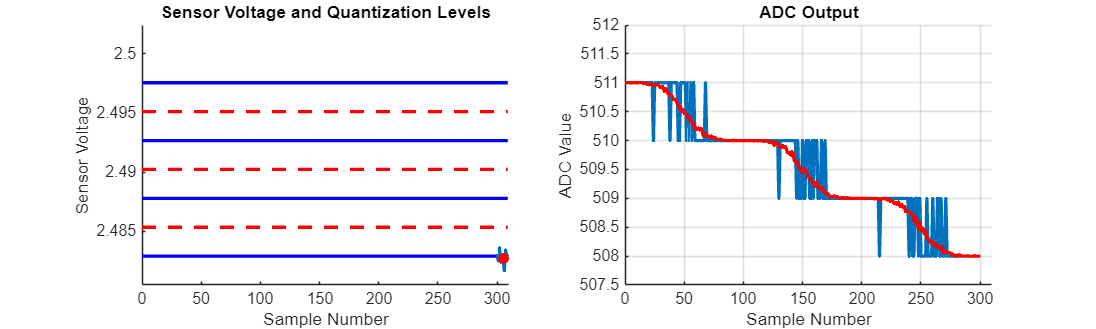

clear all

vFullScale = 5;  %  Volts
numBits = 10;
codeValue = vFullScale / (2^numBits - 1);

%  Set the number of iterations for the loop.  This is the number of times
%  that the loop will run and move the signal in voltage
numIter = 300;

%  Set the number of signal samples.  This is the length of the sequence
%  that will be drawn on the figure
numSamples = 10;

%  Drift over N = 3 of code values in numSamples time
%  Compute the amount of drift per sample
nCVDrift = 3;
driftRate = nCVDrift * codeValue / numIter;

%  Set the sensor noise as a function of the code value
sensorNoiseScale = 0.1;
ditherNoiseScale = 0.1;
totalNoiseScale = sqrt(sensorNoiseScale^2 + ditherNoiseScale^2);

sensorNoise = totalNoiseScale * codeValue;

overSampleAverage = true;
%  Change the averaging number.  This is the number of samples per point
overSampleRate = 160;

 

%  Create a signal with noise that will drift over time

signalMean = 511/1023 * 5;  %  Volts.  Mid ADC range

%  Create a figure to plot the signal within

hFig = figure;
boxSize = hFig.Position;
boxSize(3) = 2000;
boxSize(4) = 600;
hFig.Position = boxSize;

grid on
hAx1 = subplot(1,2,1);
hAx1.XLim = [0, numIter+numSamples];
hAx1.YLim = [signalMean - nCVDrift*codeValue-codeValue/2,2.5+codeValue/2];
title('Sensor Voltage and Quantization Levels')
xlabel('Sample Number');
ylabel('Sensor Voltage')


%  Draw lines at each quantization level
qLevel1 = signalMean;
qLevel2 = signalMean-codeValue * 1;
qLevel3 = signalMean-codeValue * 2;
qLevel4 = signalMean-codeValue * 3;

line(hAx1, [0,numIter+numSamples-1],[qLevel1, qLevel1],'Color','b','LineStyle','-','LineWidth',2);
line(hAx1, [0,numIter+numSamples-1],[qLevel2, qLevel2],'Color','b','LineStyle','-','LineWidth',2);
line(hAx1, [0,numIter+numSamples-1],[qLevel3, qLevel3],'Color','b','LineStyle','-','LineWidth',2);
line(hAx1, [0,numIter+numSamples-1],[qLevel4, qLevel4],'Color','b','LineStyle','-','LineWidth',2);

%  Draw lines at each threshold level
threshLevel1 = signalMean-codeValue/2;
threshLevel2 = signalMean-codeValue * 3/2;
threshLevel3 = signalMean-codeValue * 5/2;

line(hAx1, [0,numIter+numSamples-1],[threshLevel1, threshLevel1],'Color','r','LineStyle','--','LineWidth',2);
line(hAx1, [0,numIter+numSamples-1],[threshLevel2, threshLevel2],'Color','r','LineStyle','--','LineWidth',2);
line(hAx1, [0,numIter+numSamples-1],[threshLevel3, threshLevel3],'Color','r','LineStyle','--','LineWidth',2);


%  Compute the initial value of the noise signal and plot it.  Average up
%  numbSamplesPerPoint across the rows
signal = signalMean + sensorNoise * randn( numSamples, overSampleRate);
x = [0:numSamples-1];
hSensor = line(hAx1, x, signal(:,1),'LineWidth',2);
hold on

%  Place a single RED point at the mid-signal value
midSampleIndex = floor(length(signal(:,1))/2);
midSignalValue = signal(midSampleIndex,1);
hPoint = scatter(hAx1, midSampleIndex, midSignalValue,'Marker','o',...
    'MarkerEdgeColor','r',...
    'MarkerFaceColor','r');

hAx2 = subplot(1,2,2);
grid on

hAx2.XLim = [0, numIter+numSamples];
hAx2.YLim = hAx1.YLim / codeValue;
% hAx2.YLim = [signalMean - nCVDrift*codeValue-codeValue/2,signalMean+codeValue/2];
title('ADC Output')
xlabel('Sample Number');
ylabel('ADC Value')



%   Compute the initial value of the quantized signal and plot it on the
%   graph

[qValueNoAverage, qValueAverage] = Quantize(signal, [qLevel1, qLevel2, qLevel3, qLevel4] );
qValueNoAverage = qValueNoAverage / codeValue;
qValueAverage = qValueAverage / codeValue;
hADC = line(hAx2, 0, qValueNoAverage,'LineWidth',2);
hold on

if overSampleAverage
    hOSA = line(hAx2, 0, qValueAverage, 'LineWidth',2,'Color','r');
end

for iSample = 1:numIter
    
    %  Change the mean of the signal by the drift rate times the sample
    %  iteration.  This will move the mean by the driftRate per sample
    %
    %  Reduce the signalMean by 1 value of the driftRate each time
    
    signalMean = signalMean - driftRate;

    %  Create a signal with noise at that mean
    signal = signalMean + sensorNoise *  randn( numSamples, overSampleRate ); 


    

    hSensor.XData = [iSample:iSample + numSamples - 1];
    hSensor.YData = signal(:,1);  %  Only plot the first sample on the sensor data chart

    midSampleIndex = floor(length(signal(:,1))/2);
    midSignalValue = signal(midSampleIndex);

    hPoint.XData = [iSample + midSampleIndex];
    hPoint.YData = midSignalValue;

    %  Find the quantized value of the signal at one point and add it to
    %  the line data


    [qValueNoAverage, qValueAverage] = Quantize(signal, [qLevel1, qLevel2, qLevel3, qLevel4] );
    qValueNoAverage = qValueNoAverage / codeValue;
    qValueAverage = qValueAverage / codeValue;


    hADC.XData = [hADC.XData, iSample];
    hADC.YData = [hADC.YData, qValueNoAverage];

    if overSampleAverage
        hOSA.XData = [hOSA.XData, iSample];
        hOSA.YData = [hOSA.YData, qValueAverage];
    end

    %  Update the graphs
    drawnow
    
end

function [qValueNoAverage, qValueAverage] = Quantize( signal, qLevels )
%
%  Quantize
%
%  The function will take the middle sample of the signal array and
%  quantize it to the closest of the quantization levels provided in the
%  qLevels array
%
%
%  Input Arguments
%
%  signal -- An array of values representing the signal
%  qLevels -- An array of values representing the quantization levels
%
%  Output Arguments
%
%  qValue -- The quantized value of the signal
%

%  Quantize the input signal to one of the 4 quantization levels

%  Find the middle sample index of the signal

midSampleIndex = floor(length(signal(:,1))/2);
midSignalValue = signal(midSampleIndex,:);  % This is a row vector


%  Find the closest quantization level using averaging

[~, qIndex] = min( abs( midSignalValue' - qLevels )' );
qValues = qLevels(qIndex);


%  No averaging -- Just take the first value
qValueNoAverage = qValues(1);

%  Include averaging
qValueAverage = mean( qValues );

end
